HW #9

# 1

%1a
fs = 44100;
maxf = fs/2;
disp(['Max Freq ' num2str(maxf)])

1a 22050



%1b i
F = [15000,22500]./44100;
cheby = Digital("Chebyshev","Low",2, 4, F);
disp(['Cheby Order: ' num2str(cheby.Filter.order)]);

Cheby Order: 1



%1b ii
F = [15000,22500]./44100;
butter = Digital("Butterworth","Low",2, 4, F);
disp(['Butter Order: ' num2str(butter.Filter.order)]);

Butter Order: 1


# 2

y[n] + 0.25y[n-1] = 0.5x[n]

H(z) = 0.5 / (1+0.25*z^-1)

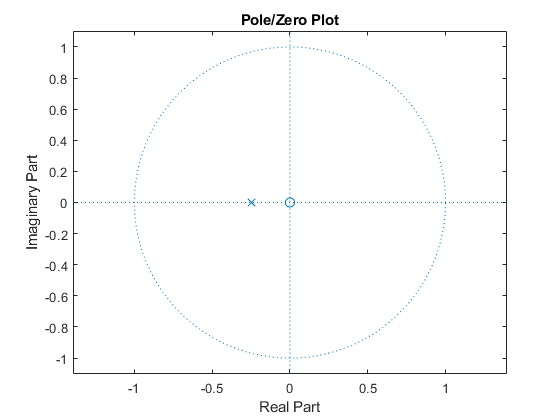

% Plot pole/zero plot
num = 0.5;
den = [1,0.25];
figure(1)
zplane(num,den)
title('Pole/Zero Plot')

h(n) = ((0.25)^n)*u[n] 

FIR because as n grows the number aproaches zero.

It is recurisive because of the refrence to a former y values with "y[n-1]"

Stable: Because the sum of the absolute value of h[n] is less than infinity

s[n] = h[n]  + s[n-1]

# 3

%Filter Creation
fs = 10000;
fpass = 1500;
fstop = 3000;
F = [fpass,fstop]./fs;
DesiredGain = 100;
DLCF = Digital("Chebyshev", "Low",1,25,F);

%Display Coefficients
DLCF.Display

**********************
Section # 1
Numerator coefficients 1 2 1
Denominator coefficients 1 -0.9827 0.66648
______________________
**********************
**********************
Section # 2
Numerator coefficients 1 1 0
Denominator coefficients 1 -0.59771 0
______________________
**********************



%Build num and den of H(z)
num = DLCF.coef(1,:,1);
den = DLCF.coef(2,:,1);
if not(length(DLCF.coef(1,1,:)) == 1)
    for n = 2:length(DLCF.coef(1,1,:))
        num = conv(num,DLCF.coef(1,:,n));
        den = conv(den,DLCF.coef(2,:,n));
    end
end

%Calcluates Correct Gain
gain = (max(abs(freqz(num, den, 1024))));
k = DesiredGain/gain;
disp(['K value: ' num2str(k)])

K value: 3.4385


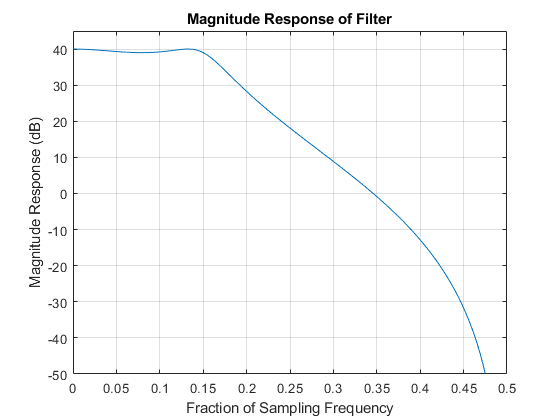

num=num*k;

%Plot Response
figure(2)
[H,w]=freqz(num,den,4096);
plot(w/2/pi,20*log10(abs(H)))
title('Magnitude Response of Filter')
ylabel('Magnitude Response (dB)')
xlabel('Fraction of Sampling Frequency')
axis([0 0.5 -50 45]);
grid on